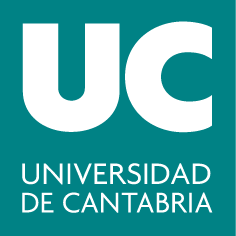

*Dpto. Matemática Aplicada y Ciencias de la Computación*

**Métodos Matemáticos en la Ingeniería**

**Bloque II: Métodos Numéricos**

# **2. Resolución numérica de ecuaciones no lineales**

## 2.1. Antecedentes matemáticos

Se define la **raíz de una ecuación** como el valor de $$x$ $que hace $$f(x) = 0$$.

Antes de aplicar métodos numéricos complejos, un análisis previo de las características de la función puede ofrecer pistas cruciales sobre la cantidad de raíces existentes y su ubicación aproximada. Este análisis, basado en conceptos como la monotonía, la convexidad y los límites, no solo ahorra tiempo de cálculo, sino que también proporciona una comprensión más profunda del problema.

**Monotonía: ** Si una función es estrictamente creciente o estrictamente decreciente en todo su dominio, solo puede cruzar el eje x una vez. Por lo tanto, tendrá como máximo una raíz real. El número de veces que una función cambia de creciente a decreciente (o viceversa) puede dar una idea del número máximo de raíces que puede tener.

**Convexidad: **La convexidad de una función describe la orientación de su curvatura y, junto con la monotonía, ayuda a refinar la búsqueda de raíces.

**Límites: **

- Si los límites en +∞ y -∞ tienen signos opuestos, la función (si es continua) debe cruzar el eje x al menos una vez, garantizando la existencia de al menos una raíz.

- Si ambos límites tienden a +∞ o -∞, la existencia de raíces dependerá de los valores que tome la función en los puntos intermedios (extremos locales).

- **Asíntotas Verticales:** En funciones racionales o con logaritmos, es crucial analizar el comportamiento cerca de las asíntotas verticales. Si la función tiende a +∞ en un lado de la asíntota y a -∞ en el otro, y la función es continua en otros lugares, es muy probable que exista una raíz.

**Estrategia Práctica para Localizar Raíces:**

- Analizar el Dominio

- Estudiar los Límites

- Calcular la Primera Derivada (Monotonía)

- Evaluar en Puntos Críticos

- Calcular la Segunda Derivada (Convexidad)

**Ejercicio (2.1)**

Determina cuántas soluciones reales tiene cada una de las siguientes ecuaciones:

- 
$$$8x = 2x^2+\cos(x)$$$


-  
$$$e^x = x^2$$$


-  
$$$e^x = \ln(-x)$$$


-  
$$$x\ln x= 1 $$$


% Representa las funciones para comprobar tus conclusiones:






Los métodos numéricos para encontrar raíces se encuentran en dos áreas de problemas relacionados, pero fundamentalmente distintos:

-  La determinación de raíces reales de ecuaciones algebraicas y trascendentes: determinar el valor de **una sola raíz** real basándose en un conocimiento previo de su posición aproximada.

- La determinación de todas las raíces reales y complejas de polinomios:  determinar sistemáticamente **todas las raíces** del polinomio en lugar de sólo una raíz real dada una posición aproximada.

En este curso se consideran los **métodos iterativos**. El algoritmo de un método iterativo consiste en los siguientes pasos:

- Tomar una aproximación inicial de la solución: $$x_0$$ (valor de partida)

- Generar una sucesión de puntos: $$$x_0 \rightarrow x_1 \rightarrow x_2 \rightarrow \ldots $$$

- La sucesión generada $$\{ x_k \}_{k=0}^{\infty}$$ cumpla $	$$\lim_{k \rightarrow \infty} x_k = x^*$$$, donde $ $x^*$$  ese la solución  de la ecuación.

Sea $$\{ x_k \}_{k=0}^{\infty}$$ una sucesión de números reales que converge hacia un punto $$x^*$$. Diremos que el **orden de convergencia** es $$p$ $(con $$p \geq 1$$) si existe una constante $$C_p >0$$ tal que


$$	$$|x_{k+1} -x^*| \leq C_p |x_k - x^*|^p, \quad \forall k \geq 0$$$$


Cuanto mayor es el orden de convergencia, más rápido converge el método.

**Clasificación de los métodos numéricos:**

* a veces la convergencia es muy lenta.

Para la aproximación inicial (el punto o el intervalo de partida), se puede utilizar el **método gráfico**:

- Graficar la función $$f(x)$;$

- Observar dónde cruza el eje $$x$$;

- Este punto ofrece una aproximación inicial de la raíz.

## 2.2. Métodos cerrados

Los métodos cerrados utilizan intervalos para encontrar raíces. Estos métodos comienzan con intervalos que contienen la raíz y luego reducen sistemáticamente el tamaño del intervalo. Se basan en el hecho de que una función cambia de signo en la vecindad de una raíz (Teorema de Bolzano). 

**Teorema de Bolzano**: Si $$f(x)$$ es continua en $$[a,b]$$ y $$$f(a)\cdot f(b) < 0,$$$ entonces 	en $$[a, b]$$ hay un número impar (al menos 1) de raíces.

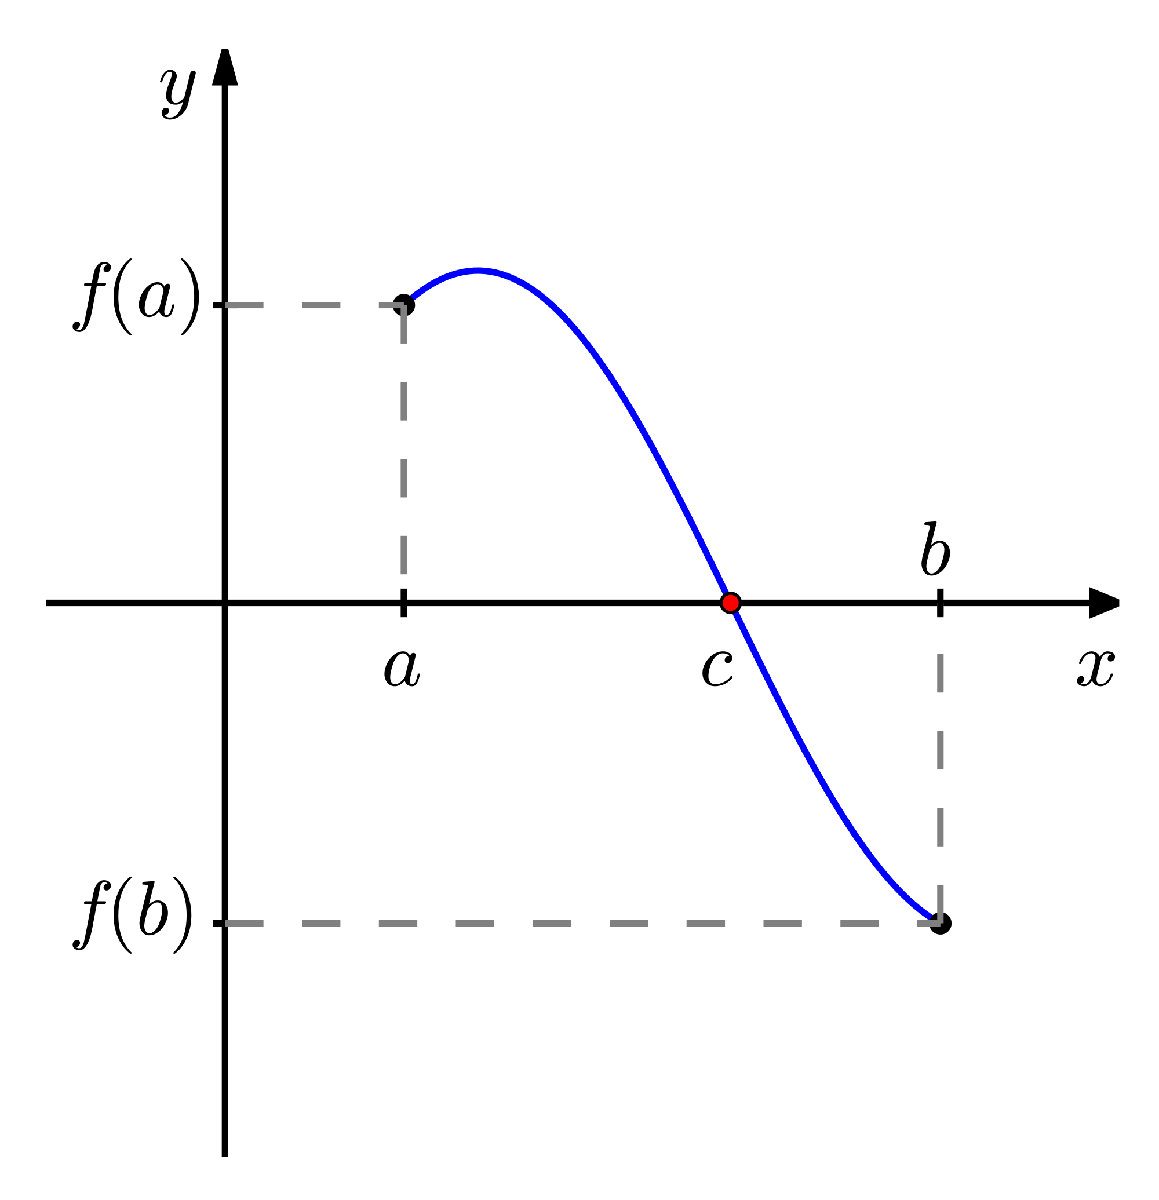

**Ejercicio (2.2)**

Para cada una de las siguientes funciones, halla un intervalo $ $[a,b]$ $de manera que $$f(a)$$ y $$f(b)$$ tengan distinto signo:

- 
$$$f(x) = e^x-2-x$$$


- 
$$f(x) = 1-x+\cos x$$


- 
$$$f(x) = \ln(x) -5+x$$$


- 
$$$f(x) = x^2-10x+23$$$


	¿Cuántas raíces tiene cada función? Verifica los resultados representado gráficamente las funciones.

% Representa las funciones para comprobar tus conclusiones:





#### Método de bisección

El método de bisección consiste en acercar sistemáticamente los extremos de un intervalo hasta obtener uno de anchura suficientemente pequeña que contenga la raíz. El proceso de subdivisión del intervalo implica tomar el punto medio del intervalo y determinar en cuál de los dos subintervalos se encuentra la raíz.

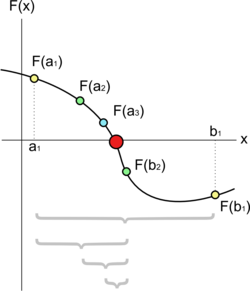

**Algoritmo del método de bisección:**

- Eligir valores $$a$$ y $ $b$$, que encierren la raíz: $$ f(a) \cdot f(b) < 0$$

- Calcular la aproximación de la raíz: $$x_r = \frac{a+b}{2}$$

-  Determinar subintervalo:

		Si$ $ f(a) \cdot f(x_r) < 0$$, entonces poner $$b = x_r$$

                Si $$ f(a) \cdot f(x_r) > 0$$, entonces poner $$a = x_r$$

                Si $$ f(a) \cdot f(x_r) = 0$$, entonces $$x_r$$ es la raíz, terminar el cálculo				

	   4. Volver al paso 2.

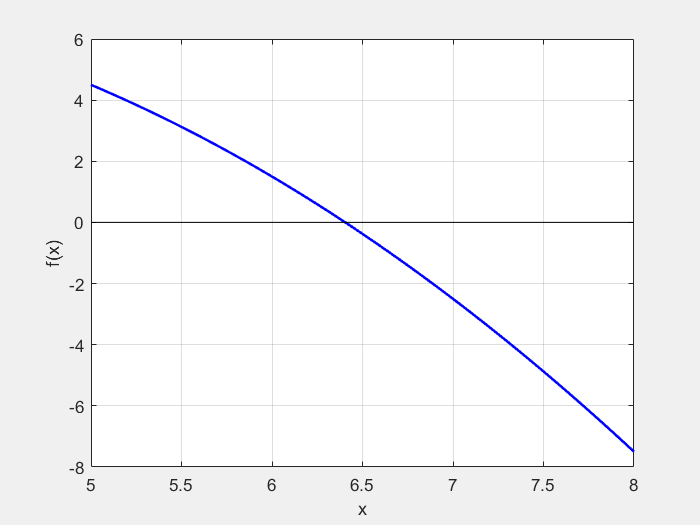

**Ejemplo (Ejercicio 2.3, apartado (a)):** Resolver la ecuación $x^2 - sen (x) = 0.25$

Primero, definimos $f(x) = x^2 - sen(x)-0.25$ y representamos graficamente la función $f(x)$:

clearvars
disp("Ejercicio (2.3) a)")
f = @(x) x.^2 - sin(x)-0.25;
fplot(f,[-2,2])
grid on

La función tiene dos raíces.

La misma conclusión se obtiene aplicando el análisis de funciones:

$f'(x) = 2x-\cos(x)$, entonces, la segunda derivada  $f''(x) = 2 + sen(x)>0 \; \forall x\in \mathbb{R}$, es positiva, $f(x)$ es convexa (decrece-crece) y tiene como máximo 2 raíces. 

Luego, como$f(0) =-0.25<0$, y $\lim_{x\to \pm \infty} f(x)  = +\infty$, entonces, $f(x)$ tiene exactamente 2 raíces, uno positivo y otro negativo.

Hallamos la raíz negativa (la raíz positiva se puede calcular de manera similar):

f(-1)

Como $f(-1) = 1.5915>0$ y $f(0) = -0.25$, elegimos el intervalo inicial $[a,b] = [-1,\, 0]$

a = -1; b = 0;      % f(a)*f(b)<0

Calculamos el punto medio del intervalo y evaluamos la función en este punto:

xr = (a+b)/2;
fr = f(xr);
fprintf("f(%f) = %f, \tf(%f) = %f, \tf(%f) = %f \n", a,f(a),xr,fr,b,f(b))

En el intervalo $[ x_r, \, b]$ la función cambia el signo, por lo tanto la raíz está en este subintervalo, ponemos $$a = x_r$$:

a=xr

Y repetimos todos los pasos:

xr = (a+b)/2;
fr = f(xr);
fprintf("f(%f) = %f, \tf(%f) = %f, \tf(%f) = %f \nLongitud del intervalo: %f", a,f(a),xr,fr,b,f(b),b-a)

Otra vez, el subintervalo que contiene la raíz es $[x_r, \, b],$ por lo tanto

a= xr;

Y repetimos todos los pasos:

xr = (a+b)/2;
fr = f(xr);
fprintf("f(%f) = %f, \tf(%f) = %f, \tf(%f) = %f \nLongitud del intervalo: %f", a,f(a),xr,fr,b,f(b),b-a)

... Así seguimos hasta obtener un intervalo de anchura suficientemente pequeña que contenga la raíz.

**Ejercicio**: Continua las iteraciones hasta que la longitud del intervalo sea menor que $10^{-4}$. ¿Cuántas iteraciones has realizado?

% escribe el código aquí





 Para comprobar el resultado:

f = @(x) x.^2 - sin(x)-0.25; a = -1; b = 0; epsilon = 0.0001;
[x_r, k, ak,bk] = biseccion( f, a, b, epsilon);
fprintf("xr = %f,\nf(%f) = %.4e,\nLongitud del itervalo: %.4e\nNúmero de iteraciones: %d\n", x_r,x_r, f(x_r),bk-ak,k)

**Ejercicio 2.3.** Implementa el método de bisección para resolver las siguientes ecuaciones:


$$ $a) \;x^2 - sen (x) = 0.25\qquad\qquad$
	b) $x \ln x -1.2 = 0\qquad\qquad$
	c) $\ln x -\frac{7}{2x+6}=0$$$


con el error absoluto $$\varepsilon < 0.0001$$.  Grafica las funciones para definir el número de raíces y el intervalo inicial $$[a,b]$$ para cada raíz. 

	Presenta los resultados en la tabla:

	

% escribe el código aquí





Una posible implementación del método de bisección

Notemos que la longitud del intervalo en cada iteración es la mitad del intervalo de la iteración anterior. Además, la sucesión de los extremos izquierdos de estos intervalos es creciente, mientras que la sucesión de los extremos derechos es decreciente:


$$a_0 \leq a_1\leq a_2\leq \ldots \leq a_n \leq \ldots \leq b_n\leq \ldots\leq b_2\leq b_1 \leq b_0 $$


**Convergencia del método de bisección**

Supongamos que $f(x)$ es una función continua en el intervalo $[a, b]$ y que $f(a) $ y $f(b)$ tienen signos distintos. Sea $\{c_n\}_{n = 0}^{\infty}$ la sucesión de puntos medios de los intervalos generados por el método de bisección. Entonces existe un número $x_r \in [a,b]$ tal que $f(x_r) = 0$ y, además, 

$|x_r - c_n| \leq \frac{b-a}{2^{n+1}}$  para $n = 0,1,\ldots$,

en particular la sucesión$\{c_n\}_{n = 0}^{\infty}$ converge a la raíz $x_r$.

Notas importantes

- Si $$f(a)f(b) <0$$ puede haber más de una raíz, al menos habrá una. El método sólo encuentra una de ellas.

- Si $$f(x)$$ no es continua en $$[a,b]$$ no está garantizado el funcionamiento del método.

- Si $$f(a)f(b) > 0$$ el método no tiene garantizado el funcionamiento.

- Se puede calcular el número de iteraciones $ $N$$ que deben realizarse para cometer un error absoluto menor o igual de un $$\epsilon$$ prefijado:

	$
	$$N \geq \frac{\ln \left(\frac{b-a}{\epsilon}\right)}{\ln 2}$$$, 

**Ejercicio 2.4:** Supongamos que usamos el método de bisección para hallar una raíz  de $$f(x)$$ en el intervalo $$[2,\, 7]$$. ¿Cuántas iteraciones se necesitan para asegurar que la aproximación tiene una precisión de $$5\times 10^{-9}$$.

*Comprueba el resultado:*

a = 2; b = 7;
epsilon = 5*1e-9;
N = ceil(log((b-a)/epsilon)/log(2))

**Ejercicio 2.5:** Para cada una de las ecuaciones del ejercicio (2.3), realiza lo siguiente:

- Utilizando el intervalo inicial $$[a,b]$$ que definiste y la tolerancia $$\epsilon~=~0.0001$$, calcula el número teórico de iteraciones (N) necesarias.

- Compara este valor teórico $$N$$ con el número de iteraciones  (n) que tu implementación necesitó.

- Comprueba y argumenta si se cumple la condición $${n = N}$$. ¿Era de esperar este resultado? ¿Por qué?

% escribe el código aquí




#### Método de la  posición falsa

Otro algoritmo popular es el método de la *régula falsi* o método de la posición falsa. Se basa en la misma idea del método de bisección, pero busca mejorar la convergencia utilizando una recta  secante $L$ que conecta los puntos extremos del intervalo. Esta secante está definida por la ecuación 


$$\frac{y-f(b)}{x-b} = \frac{f(a)-f(b)}{a-b}$$


Hallamos el punto donde la secante $L$ cruza el eje Ox:

$\frac{0-f(b)}{x_r-b} = \frac{f(b)-f(a)}{b-a}, $ de donde $x_r = b - f(b)\frac{b-a}{f(b)- f(a)}$

**Ejercicio 2.6 : **Pruebe que la fórmula del método de la posición falsa es  equivalente a $$x_r =\frac{a f(b) - b f(a)}{f(b)-f(a)}$.$

Las tres posibilidades son las mismas que antes:

- Si $ $ f(a) \cdot f(x_r) < 0$$, entonces hay una raíz en $[a, x_r]$

- Si $$ f(a) \cdot f(x_r) > 0$$, entonces hay una raíz en $[x_r, b]$

- Si $$ f(a) \cdot f(x_r) = 0$$, entonces $$x_r$$ es la raíz.

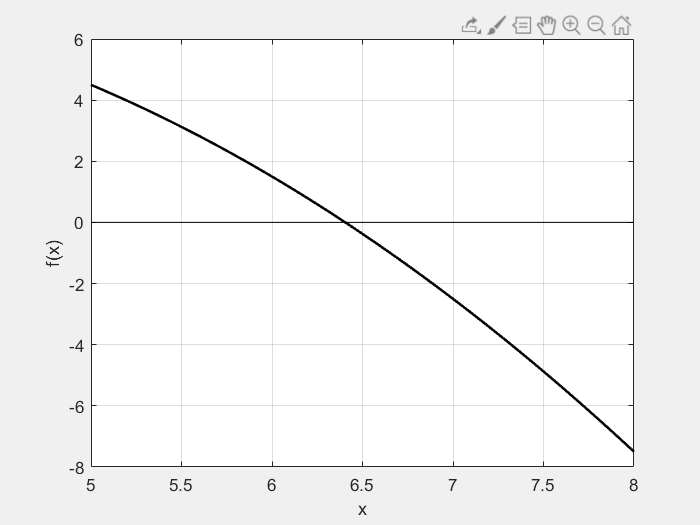

**Ejercicio 2.7: **Implementa el método de la posición falsa para resolver las siguientes ecuaciones:


$$	$a) \,8x - \cos x - 2x^2 = 0\qquad\qquad  b) \, e^x + 2^{-x} + 2 \cos x = 6$$$


con error absoluto $$\varepsilon < 0.000001$$.  Grafica las funciones para definir el número de raíces y el intervalo inicial $$[a,b]$$ para cada raíz. ¿Cuántas iteraciones ha hecho el método en cada caso?

% escribe el código aquí








**Ejercicio 2.8:** Compara la convergencia de los métodos de bisección y de falsa posición para la ecuación

	
$$$$\ln x -\frac{7}{2x+6}=0$$$$


	en el intervalo  $$(0;5)$$ con error absoluto $$\varepsilon < 10^{-6}$$. Explica los resultados. Elige el intervalo más conveniente.

% escribe el código aquí




**Ejercicio 2.9: **La velocidad $$v$$ de un paracaidista que cae está dada por


$$	$$v = \frac{gm}{c} \left( 1- e^{(-c/m)t}\right)$$$$


	donde $$g = 9.8 m/s^2$$. Para un paracaidista con coeficiente de arrastre de $$c = 15 kg/s$$, calcule la masa $$m$$ de modo que la velocidad sea $$v = 126 km/h$$ en $$t = 9s$$. Utilice el método de la  posición  falsa para determinar $$m$$ a un nivel de $$\epsilon = 0.1\%$$.

% escribe el código aquí




## 2.3. Métodos abiertos

Características comunes de los métodos abiertos:

- Se basan en fórmulas requieren un único valor de inicio o si requieren dos, no es necesario que encierren a la raíz

- No está garantizada la convergencia

- En caso de converger, lo hacen mucho más 	rápido que los métodos cerrados.

#### Iteración de punto fijo

Un **punto fijo** de una función $g(x)$ es un número real $P$ tal que $g(P) = P$

**Idea del método**: Arreglar la ecuación $$f(x) = 0$$ de tal modo que $$x$$ esté del lado izquierdo de la ecuación:

	
$$	$x = g(x)$.$$


**Algoritmo del método**

- Se despeja de manera: $$x=g(x)$$.

- Resolviendo la desigualdad $$|g' (x)|\leq 1$$, obtener el rango de valores en los cuales está el punto fijo llamado $$$x_0$$$.

- Partiendo de $$x_0$$ buscar la raíz haciendo iteraciones $$x_{k+1} = g(x_k)$, $k=0, 1, \ldots$$.

- Citerios de paro:

- 
$$|f(x_k)|<\epsilon$$
 

- 
$$$R_k= \frac{|x_{k+1}-x_k|}{|x_{k+1}|}< \epsilon$$$


- Se alcanza el número máximo de iteraciones

**Ejemplo (Ejercicio 2.10 (a)): **Resolvemos la ecuación $f(x)  = \cos(x) + 1 -x =0$ usando las iteraciones de punto fijo con tolerancia $\epsilon = 10^{-6}$.

- Despejamos $x$: $x = \cos x+1$

- $g'(x) = - sen \, x$, por tanto $$|g' (x)|\leq 1$$ se cumple $\forall x\in \mathbb{R}$. Podemos elegir cualquer punto como aproximación inicial, por ejemplo, $x_0 =1.$

- El proceso iterativo: $x_{k+1} = \cos(x_k)+1$

clearvars % borramos todo de la memoria
f = @(x) cos(x)+1-x; % f(x)
g = @(x) cos(x)+1;   % iteración de punto fijo g(x) = x
x = 1; % aproximación inicial
epsilon = 1e-6; % tolerancia

for k = 1:1000 % limitamos el número máximo de iteraciones para evitar bucles infinitos
    x(k+1) = g(x(k));
    if abs(f(x(k+1)))< epsilon || abs(x(k+1) - x(k))< epsilon*max(1,abs(x(k+1)))
        break
    end
end
x_r = x(end);
fprintf("xr = %f,\nf(%f) = %.4e,\nNúmero de iteraciones: %d\n", x_r,x_r,f(x_r),k+1)
plot(1:k+1,x,'r')
grid on
xlabel('Iteraciones, k')
ylabel('x_k')

 Elige diferentes valores para la aproximación inicial. Observa y comenta los resultados. 

**Teorema del valor medio:** Si una función$ $g(x)$$ y su primer derivada son continuas en un intervalo $$a \leq x \leq b$$, entonces existe al menos un $\xi\in[a,b]$ tal que

	
$$$$g'(\xi) = \frac{g(b)-g(a)}{b-a}$$$$


**Análisis de la convergencia	**

Definimos la solución exacta $$x_r = g(x_r)$$. Restando, se obtiene $$$x_r - x_{k+1} = g(x_r) - g(x_k)$$$

Del teorema del valor medio, existe al menos un punto  $$\xi$$ entre $$x_k$ $y $$x_r$$ que tiene una pendiente, denotada por $$g'(x)$$, que es paralela a la línea que une $$g(x_{k})$$ con $$g(x_r)$$:


$$$$g(x_r) - g(x_{k}) = g'(\xi)(x_r-x_k)$$$$


Así, $$x_r - x_{k+1} =g'(\xi)(x_r-x_k)$$. Si el error verdadero en la iteración $$k$$ se define como $$E_k = x_r-x_k$$, entonces


$$$$E_{k+1} = g'(\xi)E_k$$$$


En consecuencia, si $$|g'(x)| < 1$$, entonces los errores disminuyen con cada iteración. 

Si $$|g'(x)| > 1$$, los errores crecen. Además, si la derivada es positiva, los errores serán positivos y, por lo tanto, la solución iterativa será monótona. Si la derivada es negativa, entonces los errores oscilarán.

**Ejercicio 2.11**: Escribe el proceso iterativo de punto fijo para hallar todas las raíces de la ecuación $$f(x) = x^3+3x^2-1 = 0$$. Estudia la convergencia. 

La iteración simple de punto fijo es linealmente convergente.

#### Método de Newton-Raphson

**Idea: **Partiendo de un punto inicial $$x_0$$, calculamos la siguiente iteración haciendo la recta tangente a la curva de la función en $$x_0$$ y ver dónde corta al eje OX.

Fórmula de Newton-Raphson: Si el valor inicial para la raíz es $$x_k$$, entonces se puede trazar una tangente desde el punto $$\left(x_k, f(x_k)\right)$$ de la curva. El punto donde esta tangente cruza al eje OX representa una aproximación mejorada de la raíz:

	
$$$$x_{k+1} = x_k - \frac{f(x_k)}{f'(x_k)}$$$$


Citerios de paro:

- 
$$|f(x_k)|<\epsilon$$
 

- 
$$$R_k= \frac{|x_{k+1}-x_k|}{|x_{k+1}|}< \epsilon$$$


- Se alcanza el número máximo de iteraciones

**Ejercicio 2.12**: El antiguo método de dividir y promediar, para obtener una apoximación de la raíz cuadrada de cualquier número positivo,

$$a$$, se formula del modo siguiente:


$$$x = \frac{x+a/x}{2}$.$$


Demuestra que éste es equivalente al algoritmo de Newton-Raphson.

**Ejercicio 2.13**: Resolvemos la ecuación $f(x)  = \cos(x) + 1 -x =0$ usando el método de Newton-Raphson con tolerancia $\epsilon = 10^{-3}$ y la aproximación inicial $x_0 = 1$.

% escribe aquí el código:





Para comprobar el resultado:

f = @(x) cos(x)+1-x; x = 1; epsilon = 0.001;
fs = sym(f);
df = diff(fs)
fprime = matlabFunction(df);
[xr, k] = newton(f,fprime,x,epsilon);
fprintf('xr = %f,\nf(%f) = %.4e,\nNúmero de iteraciones: %d\n', xr,xr,f(xr),k)

 Vuelve a ejecutar el código anterior, pero elige como la aproximación inicial $x_0 = \frac{3}{2}\pi$. Explica los resultados. 

% escribe aquí el código:




**Notas importantes:**

-  Elegir el valor inicial $$x_0$$ tal  que $$$f(x_0)  f''(x_0) >0$$$ (evitar los puntos donde la pendiente es horizontal ($$f'(x)=0$$), o vertical ($$f'(x)\to\pm\infty$$)).

- El programa deberá incluir siempre un límite máximo permitido del número de iteraciones para estar prevenidos contra soluciones oscilantes, de lenta convergencia o divergentes que podrían persistir en forma interminable.

- El programa deberá alertar al usuario para que tome en cuenta la posibilidad de que $$f'(x)$$ sea igual a cero en cualquier momento durante el cálculo.

Resuelve los Ejercicios 2.14-2.15.

**Análisis de la convergencia**

La serie de Taylor se puede representar como

$$$f(x_{k + 1}) = f(x_k) + f'(x_k)(x_{k + 1} - x_k) + \frac{f''(\xi )}{2!} (x_{k + 1} - x_k)^2$$$, donde $$\xi$$ se encuentra en alguna parte del intervalo $$[x_i; x_{i+1}]$$.

Si $$x_{k+1} = x_r$$ (raíz),entonces 


$$$$f(x_{r})=0  = f(x_k) + f'(x_k)(x_{r} - x_i) + \frac{f''(\xi )}{2!} (x_{r} - x_k)^2$$$$


Por otro lado, el método de Newton-Raphson (la serie de Taylor):


$$$$f(x_{k + 1})=0  = f(x_k) + f'(x_k)(x_{k+1} - x_k)$$$$


Restamos:


$$
$$0 = f'(x_k)(x_{r} - x_{k+1}) + \frac{f''(\xi )}{2!} (x_{r} - x_k)^2$$$$


Observe que el error es igual a la diferencia:

$$E_{t, k + 1} = x_r - x_{k + 1}$$, entonces,

$$$0 = f'(x_k)E_{t,k + 1} + \frac{f''(\xi )}{2!} E_{t, k}^2$$$, de donde se obtiene que

	
$$$$E_{t, k + 1} = -\frac{f''(x_r)}{2f'(x_r)}E_{t, k}^2$$$$


Es decir, el error es proporcional al cuadrado del error anterior (**convergencia cuadrática**).

#### Método de la secante

Existen algunas funciones cuyas derivadas en ocasiones resultan muy difíciles de calcular.

Idea del método: La derivada se puede aproximar mediante una diferencia finita dividida hacia atrás:


$$$$f'(x_k) \approx \frac{f(x_{k}) - f(x_{k-1})}{x_k- x_{k-1}}$$$$


Iteraciones del método de la secante: $$$x_{k+1} = x_k - \frac{f(x_k) (x_k - x_{k-1})}{f(x_k) - f(x_{k-1})}$$$

**Ejercicio 2.16**: Utilice los métodos de la secante y de la posición falsa para calcular la raíz de $$f(x) = x^3 - cos(x)$$. Empiece los cálculos con los valores iniciales $$a = x_{k-1}= 0.5$$ y $$b = x_k = 5.0$$.

% escribe aquí el código:






#### Comando `fzero`

La función `fzero` busca una raíz de la función$f(x)$ tal que$f(x) =0$. Este método es adecuado para funciones continuas y se basa en una combinación de los métodos de búsqueda de raíces como bisección, método de la secante y el método de interpolación inversa cuadrática.

**Sintaxis Básica**

- `fun`: Especifica la función cuya raíz se desea encontrar. Puede ser un handle a una función, una cadena que nombre una función, o una función anónima.

- `x0`: Punto inicial o estimación inicial para la raíz.

- `[x1, x2]`: Intervalo donde se busca la raíz, con $f(x1) \;y\;  f(x2)$ de signos opuestos.

- `root`: La raíz encontrada.

- `fval`: Valor de la función en la raíz encontrada (debe ser cercano a cero).

- `exitflag`: Indicador de éxito o razón de terminación.

- `output`: Estructura con información sobre el proceso de búsqueda.

Ejemplo: Resolvemos la ecuación $f(x)  = \cos(x) + 1 -x =0$ usando el comando `fzero` y la aproximación inicial $x_0 = \frac{3}{2}\pi$.

f =@(x) cos(x)+1-x;
x0 =3*pi/2;
[root, fval, exitflag, output] = fzero(f,x0)

## Bibliografía

- [Chapra S.C.; Canale R. (2015) Métodos Numéricos para Ingenieros. Ed. McGRaw-Hill](https://catalogo.unican.es/cgi-bin/abnetopac?TITN=436963) (Capítulos 5-8)

- [Mathews J.H., Fink K.D. (2000) Métodos Numéricos con MATLAB. Ed. Prentice Hall](https://catalogo.unican.es/cgi-bin/abnetopac?TITN=163396) (Capítulo 2)

Funciones auxiliares

1. Método de bisección

function [ x_r,k ,ak,bk] = biseccion( f, a, b, epsilon)
% f - función anónima cuya raíz se quiere aproximar: f(x) = 0
% a, b - los extremos del intervalo inicial
% epsilon - la tolerancia
% x_r - aproximación de la raíz
% k - número de iteraciones

if (f(a)*f(b)<0) % condición del Teorema de Bolzano
    N = 1 + round(log(b-a)-log(epsilon)/log(2)); % número máximo de iteraciones
    for k = 1:N
        x_r = (a+b)/2;
        if (f(a)*f(x_r)<0)
            b = x_r;
        else
            a =x_r;
        end
        if abs(a-b)<epsilon 
            break
        end
    end
else
    fprintf("En intervalo inicial no cumple la condición del Teorema de Bolzano.\n")
end
ak = a; bk = b;
end

2. Método de Newton

function [x, k] = newton(f,fprime,x,epsilon)
N_max = 100; % número máximo de iteraciones
% bucle principal:
for k=1:N_max
    df = fprime(x);
    if abs(df)>eps
        % calculamos el incremento dx = f(x)/f'(x):
        dx  = f(x)/fprime(x);
        x = x - dx;
        % comprobamos los criterios de paro:
        if abs(dx)< epsilon * max(1, abs(x)) || abs( f(x))<epsilon
            break;
        end
    else
        fprintf("El método diverge!")
        x = NaN; 
        break
    end
end
end